### **Иван Шаламов, 551 группа. Лабораторная работа № 3, 2020.**

% TODO: 1) Переделать график с эпюрами. 
% 2) Рассмотреть версию с векторами.

clc;
close all;
clear;
opengl software;

### **Практическая часть.**

Общие параметры.

TextSize = 15;

Ym = 20; % размер расчетной области по eta
Eps = 1e-6; % заданная точность рассчета
beta = 0.3; % параметр нижней релаксации
NIterLim = 400; % максимальное количество итераций

N = 1001; % число узлов
M = 3; % число уравнений
h = Ym / (N - 1); % шаг сетки

Инициализация переменных.

UOld = zeros(N*M, 1); % вектор решений на итерациях n
UNew = UOld; % вектор решений на итерациях n+1
B=zeros(N*M,1); % вектор правых частей
SErr=[]; % массив погрешностей

Основной итерационный цикл по нелинейности.

step = 0;

while (step < NIterLim)
    
    step = step + 1;
    
    % Обнуление массивов, описывающих разреженную матрицу:
    indI = [];
    indJ = [];
    sIJ = [];
    
    % Заполнение разреженной матрицы коэффициентами для внутренних точек:
    for i = 1:(N-1)
        
        iL1 = (i - 1) * M + 1; % индекс 1-й переменной в узле i
        iR1 = i * M + 1; % индекс 1-й переменной справа от узла i
        iL2 = (i - 1) * M + 2; % индекс 2-й переменной в узле i
        iR2 = i * M + 2; % индекс 2-й переменной справа от узла i
        iL3 = (i - 1) * M + 3; % индекс 3-й переменной в узле i
        iR3 = i * M + 3; % индекс 3-й переменной справа от узла i
        
        iEq = (i - 1) * M + 1; % номер уравнения (1-е)
        
        % Составление 1-го уравнения (разность вправо):
        indI = [indI iEq iEq iEq    iEq]; % номера уравнений
        indJ = [indJ iR1 iL1 iL2    iR2]; % номера переменных
        sIJ  = [sIJ  1   -1  -0.5*h -0.5*h]; % значения коэффициентов при переменных
        B(iEq) = 0;
        
        iEq = (i - 1) * M + 2; % номер уравнения (2-е)
        
        % Составление 2-го уравнения:
        indI = [indI iEq iEq iEq    iEq];
        indJ = [indJ iR2 iL2 iR3    iL3];
        sIJ  = [sIJ  1   -1  -0.5*h -0.5*h];
        B(iEq) = 0;
        
        iEq = (i - 1) * M + 3; % номер уравнения (3-е)
        
        % На каждой итерации решается линеаризованная система:
        Old1 = 0.5 * (UOld(iR1) + UOld(iL1));
        Old3 = 0.5 * (UOld(iR3) + UOld(iL3)); % значения на предыдущей итерации
        
        % Составление 3-го уравнения:
        indI = [indI iEq                iEq                 iEq             iEq];
        indJ = [indJ iR3                iL3                 iR1             iL1];
        sIJ  = [sIJ  1+0.25*h*Old1    -1+0.25*h*Old1    0.25*h*Old3     0.25*h*Old3];
        B(iEq) = h * 0.5 * (Old1 .* Old3);
        
    end
    
    % Добавляем граничные условия в конец матрицы:
    
    % Левые ГУ для f1:
    indI = [indI (N-1)*M+1]; % номер уравнения
    indJ = [indJ 1]; % номер переменной, где задано ГУ
    sIJ = [sIJ 1];
    B((N-1)*M+1) = 0; % значение ГУ
    
    % Левые ГУ для f2:
    indI = [indI (N-1)*M+2];
    indJ = [indJ 2];
    sIJ = [sIJ 1];
    B((N-1)*M+2) = 0;
    
    % Левые ГУ для f3 отсутствуют
    
    % Правые ГУ для f2
    indI = [indI (N-1)*M+3]; % номер уравнения
    indJ = [indJ (N-1)*M+2]; % номер переменной (f2)
    sIJ = [sIJ 1];
    B((N-1)*M+3) = 1;
    
    % Правые ГУ для f1, f3 не заданы
    
    % Формирование матрицы:
    A = sparse(indI, indJ, sIJ);
    
    % Решение системы:
    UNew = A \ B;
    
    % Погрешность:
    z = max(abs(UOld-UNew));
    SErr = [SErr z];
    
    if z < Eps
        
        break;
        
    end
    
    % Нижняя релаксация:  
    UOld = (1 - beta) * UOld + beta * UNew;
    
end

Извлечение решения из общего массива неизвестных.

eta = (0:Ym/(N-1):Ym)';
f1 = UOld((0:N-1)*M+1);
f2 = UOld((0:N-1)*M+2);
f3 = UOld((0:N-1)*M+3);

Визуализация решения.

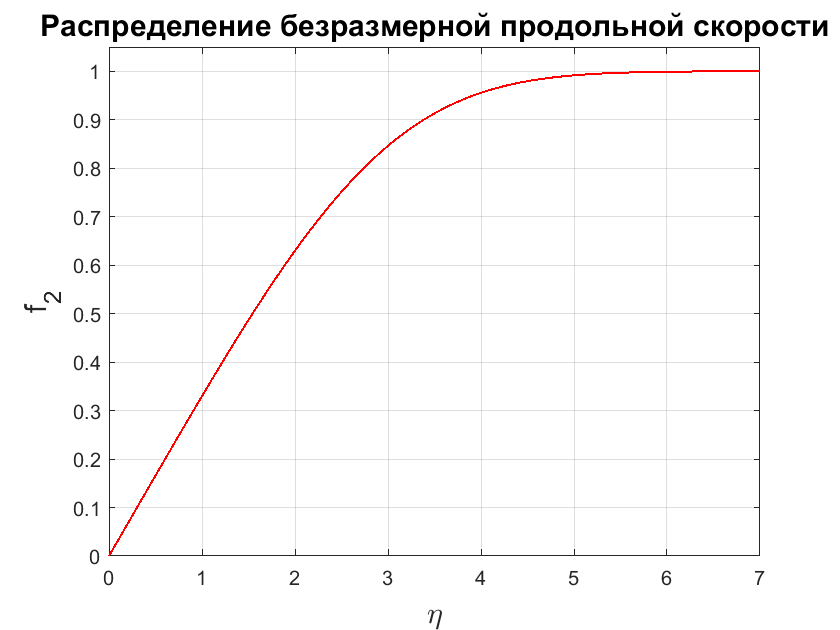

figure(1);
plot(eta, f2, '-r', 'LineWidth', 1);
grid on;
title('Распределение безразмерной продольной скорости', 'FontSize', TextSize);
xlabel('\eta', 'FontSize', TextSize);
ylabel('f_2', 'FontSize', TextSize);
xlim([0, 7]);
ylim([0, 1.05]);

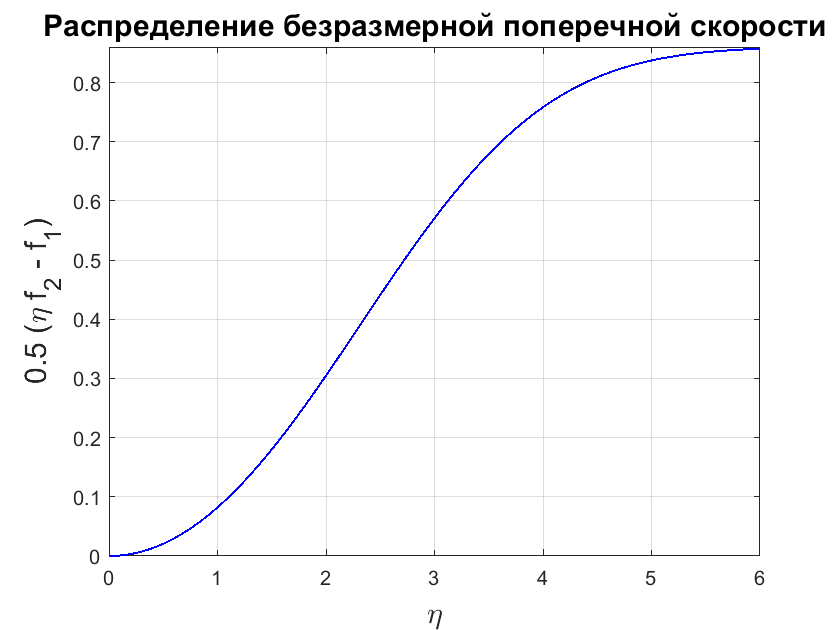

figure(2);
plot(eta, 0.5*(eta.*f2 - f1), '-b', 'LineWidth', 1);
grid on;
title('Распределение безразмерной поперечной скорости', 'FontSize', TextSize);
xlabel('\eta', 'FontSize', TextSize);
ylabel('0.5 (\eta f_2 - f_1)', 'FontSize', TextSize);
xlim([0, 6]);
ylim([0, 0.86]);

### **Исследовательская часть.**

Параметры пластины и потока.

l = 1; % длина пластины, м
nu = 1.006; % кинематическая вязкость, м^2/c
U_inf = 1000; % скорость набегающего потока, м/c

Нахождение коэффициента α.

fprintf(['В данной работе коэффициент α = %.3f, ' ...
    '\nчто соответствует табличному значению.'], f3(1));

В данной работе коэффициент α = 0.332, 
что соответствует табличному значению.

Вычисление коэффициента сопротивления.

Re_l = U_inf * l / nu; % число Рейнольдса

c_f = 1.328 / sqrt(Re_l); % коэффициент сопротивления

fprintf(['Для пластины длиной l = %d м при скорости набегающего ' ...
    '\nпотока U∞ = %d м/с: число Рейнольдса = %.1f, ' ...
    '\nкоэффициент сопротивления = %.4f.'], l, U_inf, Re_l, c_f);

Для пластины длиной l = 1 м при скорости набегающего 
потока U∞ = 1000 м/с: число Рейнольдса = 994.0, 
коэффициент сопротивления = 0.0421.

Нахождение толщины пограничного слоя. Вычисление распределений продольной скорости u вдоль координаты y для различных сечений x.

x = [0.1, 0.3, 0.5]; % сечение пластины, м
delta = sqrt(nu * x / U_inf); % толщина пограничного слоя, м

y = eta * delta;
u = f2 * U_inf;

Вывод результатов.

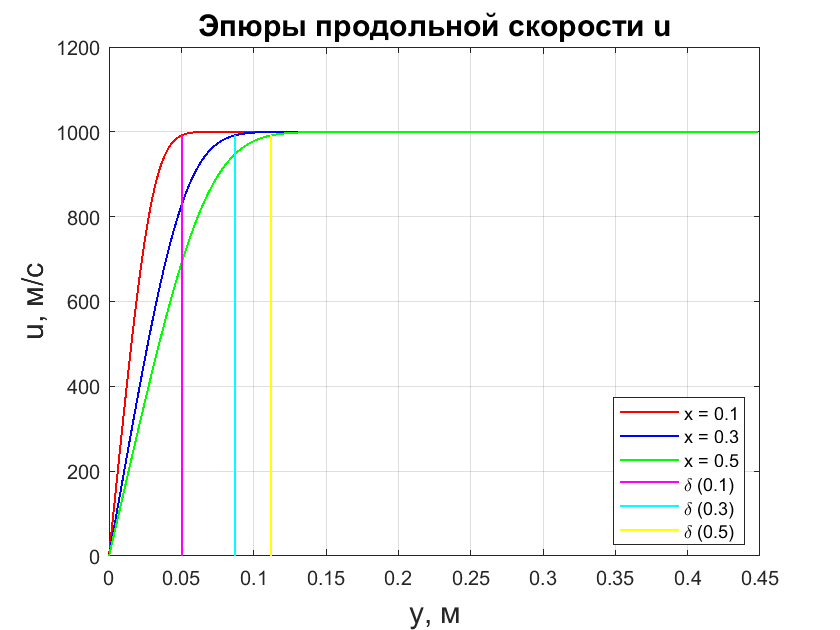

figure(3);
plot(y(:,1), u, '-r', y(:,2), u, '-b', y(:,3), u, '-g', ...
    [y(y(:, 1)==5*delta(1), 1), y(y(:, 1)==5*delta(1), 1)], ...
    [u(1), u(y(:, 1)==5*delta(1))], '-m', ...
    [y(y(:, 2)==5*delta(2), 2), y(y(:, 2)==5*delta(2), 2)], ...
    [u(1), u(y(:, 2)==5*delta(2))], '-c', ...
    [y(y(:, 3)==5*delta(3), 3), y(y(:, 3)==5*delta(3), 3)], ...
    [u(1), u(y(:, 3)==5*delta(3))], '-y', 'LineWidth', 1);
grid on;
title('Эпюры продольной скорости u', 'FontSize', TextSize);
xlabel('y, м', 'FontSize', TextSize);
ylabel('u, м/с', 'FontSize', TextSize);
legend('x = 0.1', 'x = 0.3', 'x = 0.5', ...
    '\delta (0.1)', '\delta (0.3)', '\delta (0.5)', 'Location', 'best');